clear; clc; close all;

%% Parâmetros do sinal e amostragem
A = 2;          % Amplitude
f = 1000;       % Frequência do sinal (Hz)
fs = 8000;      % Frequência de amostragem (Hz)
N = 32;         % Número de amostras
periodo_fs = 1/fs;
periodo_f = 1/f;

% intervalo de amostragem
dt = periodo_fs/N

dt = 3.9063e-06


n = zeros(1,N);
t = zeros(1,N);

for i=0:1:(N-1)
    n(i+1) = i;
    t(i+1) = n(i+1)*dt;
end
disp(t)

   1.0e-03 *

         0    0.0039    0.0078    0.0117    0.0156    0.0195    0.0234    0.0273    0.0312    0.0352    0.0391    0.0430    0.0469    0.0508    0.0547    0.0586    0.0625    0.0664    0.0703    0.0742    0.0781    0.0820    0.0859    0.0898    0.0938    0.0977    0.1016    0.1055    0.1094    0.1133    0.1172    0.1211




% Substituindo t por n/fs no sinal analítico:
x_n = A * sin(2 * pi * f * (n / fs)); 

% Exibe os valores de x[n] no Command Window
disp('Amostras de x[n]:');

Amostras de x[n]:


disp(x_n);

         0    1.4142    2.0000    1.4142    0.0000   -1.4142   -2.0000   -1.4142   -0.0000    1.4142    2.0000    1.4142    0.0000   -1.4142   -2.0000   -1.4142   -0.0000    1.4142    2.0000    1.4142    0.0000   -1.4142   -2.0000   -1.4142   -0.0000    1.4142    2.0000    1.4142    0.0000   -1.4142   -2.0000   -1.4142



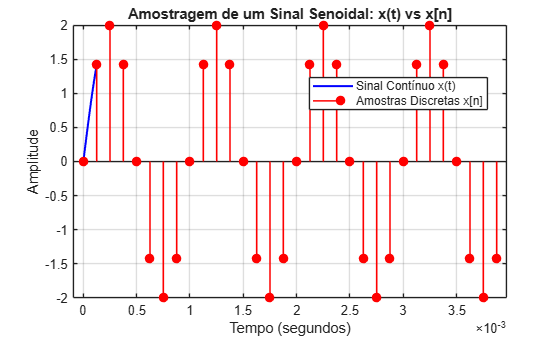


%% (b) Representação de x(t) com resolução suficientemente elevada
% O intervalo de tempo deve cobrir o mesmo intervalo ocupado pelas amostras.

x_t = A * sin(2 * pi * f * t);      % Sinal contínuo simulado

%% (c) Plotagem dos gráficos na mesma figura
figure;
% Representação de x(t) por uma linha contínua
plot(t, x_t, 'b-', 'LineWidth', 1.5); 
hold on;

% Representação das amostras x[n] posicionadas corretamente no tempo (t_n = n/fs)
t_n = n / fs;
stem(t_n, x_n, 'r', 'Filled', 'LineWidth', 1.2); 

% Identificação de eixos, legenda, título e grade
xlabel('Tempo (segundos)');
ylabel('Amplitude');
title('Amostragem de um Sinal Senoidal: x(t) vs x[n]');
legend('Sinal Contínuo x(t)', 'Amostras Discretas x[n]', 'Location', 'Best');
grid on;
hold off;


%% (d) Cálculo do período de amostragem e amostras por período
Ts = 1 / fs;        % Período de amostragem
Np = fs / f;        % Número de amostras por período da senoide

% Exibe os resultados calculados
fprintf('\n--- Resultados Calculados ---\n');


--- Resultados Calculados ---


fprintf('Período de amostragem (Ts): %e segundos (%.3f ms)\n', Ts, Ts*1000);

Período de amostragem (Ts): 1.250000e-04 segundos (0.125 ms)


fprintf('Número de amostras por período (Np): %.1f amostras/período\n', Np);

Número de amostras por período (Np): 8.0 amostras/período
